importstl = stlread('Bennu STLS\Bennu Radar.stl');

x = importstl.Points(:,1)+0.3;
y = importstl.Points(:,2)+0.3;
z = importstl.Points(:,3)-0.3;
tri = delaunay(x,y);

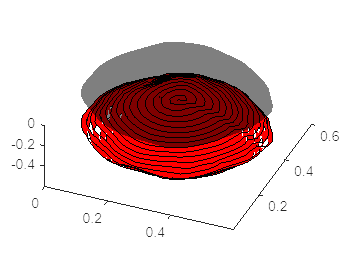

fill3(x,y,z, 'r')

n = length(x);
dx = zeros(n,1);
dy = zeros(n,1);
dz = zeros(n,1);

% px = patch('Faces',tri,'Vertices',[dx y z]);
% py = patch('Faces',tri,'Vertices',[x dy z]);
pz = patch('Faces',tri,'Vertices',[x y dz]);
set([pz],'FaceAlpha',.5,'EdgeColor','none');